clear
close all
clc

The goal of this code is to apply the theory of sensor fusion to a practical case

**SECTION: loading up data**

It is important that within the following cell the path corresponds with the path that is currently used. Also include a global variable for the amount of points that are required for the grid.

% note that the folder path is the correct one
folder_path = 'C:\Users\giaco\OneDrive\Desktop\Università\Mag_1_Anno\1_Semestre\Robotic_perception\Project_SensorFusion';
folder_path_grid = 'C:\Users\giaco\OneDrive\Desktop\Università\Mag_1_Anno\1_Semestre\Robotic_perception\Project_SensorFusion\Grid';
num_points = 33;

Load the position of the robots. This includes the right wheel, leftwheel, ground, and both trajectories that were tracked. The right wheel, left wheel and ground measurements were done at the beginning. The trajectory contains the quaternion, rotation and timestamp of the measurement whereas the outputE contains the ticks of the left encoder, the ticks of the right encoder and the timestamp. All of these measurements were done in reference frame camera "a": (r.f. camera "a").

rightwheel_a = load('Data\rightwheel.csv');  % the left wheel measurement data (r.f. camera "a")
leftwheel_a = load('Data\leftwheel.csv');    % the right wheel measurement data (r.f. camera "a")
g_a = load('Data\ground.csv');               % the ground measurement data (r.f. camera "a")
trajectory_unfiltered = load('Data\trajectory.csv');    % trajectory from the sensor (r.f. camera "a")
outputE = load('Data\output_enc.txt');       % trajectory from the encoder (r.f. encoders "e")

Point 19 is considered as the center of the grid, which represents the room environment. This means that this is the center of the room seen by camera "a": (r.f. camera "a").

o_a = load('Grid\data_point_19.csv');    % the first, second and third elements are respectively the x, y and z coordinates

To reduce the computational effort required, we remove excess rows with the same timestamp

timestamps = trajectory_unfiltered(:, end);         % Get the column with the timestamps

[~, unique_idx] = unique(timestamps, 'first');      % Save the rows with unique timestamps

trajectory = trajectory_unfiltered(unique_idx, :);  % Keep the rows with unique timestamps

**SECTION: defining raw variables from raw data**

Defining the position of the two wheels from data (r.f. camera "a").

r_a = [rightwheel_a(1, 1), rightwheel_a(1, 2), rightwheel_a(1, 3), 1]

r_a =    -0.1365   -1.4122   -3.4133    1.0000


l_a = [leftwheel_a(1, 1), leftwheel_a(1, 2), leftwheel_a(1, 3), 1]

l_a =    -0.7632   -1.3267   -3.5504    1.0000


Defining the initial position in the trajectory of the sensor and its initial orientation via quaternions q (r.f. camera "a").

s_a = [trajectory(1, 1), trajectory(1, 2), trajectory(1, 3), 1];
q_s_a = [trajectory(1, 4), trajectory(1, 5), trajectory(1, 6), trajectory(1, 7)];

Defining the orientation of the sensor on the ground measurement with respect to the  camera orientation (in quaternion notation).

q_g_a = [g_a(1, 4), g_a(1, 5), g_a(1, 6), g_a(1, 7)];

**SECTION: elaborating raw variables to define useful variables**

This is the rotation matrix that takes data in the r.f. of the ground and outputs them in the r.f. camera "a". The rotation around x of 90 degrees is due to the orientation of the sensor frame (needs to be rotated to get a more comfortable r.f.).    

Rag = quat2rotm(q_g_a) * rotx(90)   

Rag =    -0.9983   -0.0480   -0.0326
    0.0565   -0.9330   -0.3555
   -0.0134   -0.3567    0.9341


Determining the initial middle point with respect to r.f."a". Note that this point should coincide with "e_a" the origin of the encoder r.f. Also the orientation of the origin is defined through quaternions.

m_a = [(r_a(1) + l_a(1)) / 2 (r_a(2) + l_a(2)) / 2 (r_a(3) + l_a(3)) / 2 1]

m_a =    -0.4498   -1.3695   -3.4819    1.0000


q_o_a = [o_a(1, 4), o_a(1, 5), o_a(1, 6), o_a(1, 7)];

Building the rototranslation from the room r.f. "o" to the r.f. camera "a".

Rao = quat2rotm(q_o_a) * roty(180);
mean_o_a = [mean(o_a(:, 1)), mean(o_a(:, 2)), mean(o_a(:, 3)), 1];
Mao = [Rao, mean_o_a(1:3)'; 0 0 0 1];
Moa = inv(Mao);

Building and normalizing the perpendicular vetor to the ground.

z_g_a = -Rag(:,2)' / norm(Rag(:, 2))

z_g_a =     0.0480    0.9330    0.3567


 Building and normalizing the wheel axis.

t1 = (l_a-r_a)/norm(l_a-r_a); % temporary variable 1, used immediately after this in the next line
y_e_a = -t1(1:3)

y_e_a =     0.9684   -0.1321    0.2118


Veryfing that the two vectors are perpendicular, if not it's suggested to retake the ground measurement to be more precise or the wheel axis to be more accurate, FINAL RESULT STRONGLY DEPENDS ON THIS. It should be close to 0.

dot(z_g_a,y_e_a)

ans = -0.0012

 building and normalizing the x axis of the encoders model r.f..

x_e_a = cross(z_g_a,y_e_a) / norm(cross(z_g_a, y_e_a))

x_e_a =     0.2447    0.3353   -0.9098


Verifying that the two vectors are perpendicular, if it is not then it is suggested to retake the ground measurement to be more precise or the wheel axis to be more accurate. FINAL RESULT STRONGLY DEPENDS ON THIS.

dot(z_g_a,x_e_a)

ans = 1.7347e-17

dot(x_e_a,y_e_a)

ans = 0

defining the z axis for the encoders model r.f..

z_e_a = cross(y_e_a,x_e_a)

z_e_a =     0.0492    0.9328    0.3570


building the rotation matrix from the encoder r.f. "e" to the r.f. camera "a"  and obtain its inverse.

Rae = [x_e_a' y_e_a' z_e_a']

Rae =     0.2447    0.9684    0.0492
    0.3353   -0.1321    0.9328
   -0.9098    0.2118    0.3570


Rea = inv(Rae)

Rea =     0.2447    0.3353   -0.9098
    0.9684   -0.1321    0.2118
    0.0492    0.9328    0.3570


building the rototranslation matrix from the encoder r.f. "e" to the r.f. camera "a" and obtain its inverse.

Mae = [Rae m_a(1:3)'; 0 0 0 1 ]

Mae =     0.2447    0.9684    0.0492   -0.4498
    0.3353   -0.1321    0.9328   -1.3695
   -0.9098    0.2118    0.3570   -3.4819
         0         0         0    1.0000


Mea = inv(Mae)

Mea =     0.2447    0.3353   -0.9098   -2.5985
    0.9684   -0.1321    0.2118    0.9920
    0.0492    0.9328    0.3570    2.5426
         0         0         0    1.0000


building the rotation matrix from the sensor r.f. "s" to the r.f. camera "a".

Ras = quat2rotm(q_s_a);

building the rototranslation matrix from the sensor r.f. "s" to the r.f. camera "a"  and obtain its inverse.

Mas = [Ras s_a(1:3)'; 0 0 0 1]

Mas =    -0.9591    0.2819   -0.0261   -0.5164
    0.1219    0.3279   -0.9368   -0.9475
   -0.2555   -0.9017   -0.3489   -3.8565
         0         0         0    1.0000


Msa = inv(Mas)

Msa =    -0.9591    0.1219   -0.2555   -1.3652
    0.2819    0.3279   -0.9017   -3.0210
   -0.0261   -0.9368   -0.3489   -2.2466
         0         0         0    1.0000


rototranslating the middle point m from r.f. camera "a" to the sensor r.f. "s".

m_s = Msa * m_a'

m_s =    -0.2110
   -0.4574
    0.2628
    1.0000


Defining the rototraslation matrix from the encoders r.f. "e" to the r.f. "o", the point chosen to be the origin of the room reference frame.

Moe = Moa * Mae;

For simplicity a rotation matrix of 90 degrees is defined.

RotMatrix = [cos(pi / 2) -sin(pi / 2); sin(pi / 2) cos(pi / 2)];

**SECTION: middle point trajectory generated by the sensor trajectory **

For each instant of the trajectory this for loop takes in input the sensor position and orientation with respect to "a" and outputs the middle point position with respect to "e" and with respect to "o".

for i = 1:length(trajectory)
    s_a = [trajectory(i, 1), trajectory(i, 2), trajectory(i, 3), 1];
    q_s_a = [trajectory(i, 4), trajectory(i, 5), trajectory(i, 6), trajectory(i, 7)];  

    Ras = quat2rotm(q_s_a);
    Res = Rea*Ras;

    s_e = Mea*s_a';

    Mes =[Res s_e(1:3) ; 0 0 0 1];

    m_e(i, 1:4) = Mes*m_s;
    
    s_o(i, 1:4) = Moe*s_e;
end

Rototranslating the middle point from the r.f. "e" to the r.f. "o".

m_o = Moe * m_e'

m_o =     0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1181    0.1176    0.1176    0.1176    0.1176    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1180    0.1179    0.1179    0.1180    0.1180    0.1179    0.1179    0.1179    0.1179    0.1178    0.1178    0.1178    0.1178    0.1178    0.1178    0.1178    0.1178    0.1178    0.1178
   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3580   -1.3580   -1.3580   -1.3580   -1.3587   -1.3587   -1.3587   -1.3587   -1.3587   -1.3587   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3586   -1.3583   -1.3583   -1.3582   -1.3582   -1.3582   -1.3582   -1.3582   -1.3582   -1.3582   

**SECTION: middle point trajectory generated by the encoder model**

IMPORTANT NOTE: since the middle point is generated by two different methods it should have two different names to distinguish the two. Also to avoid overwriting the data, the chosen name to indicate the middle point computed with the encoder model is "enc_x" where "x" is the r.f..

Defining the data needed for the encoder model.

wheel_radius_R = 0.170;                     % right wheel radius
wheel_radius_L = 0.170;                     % left wheel radius
wheel_base = 0.572;                         % wheel distance (base)
enc_N0 = 72000;                             % number of ticks of the encoder in a circonference


Defining the length of the dataset generated by the the encoders.

N1 = length(outputE(:, 1));

Defining phi as a variable consisting of the x location, y location, and delta (angle) with respect to the r.f. "e".

phi_new = zeros(N1 , 3);    % empty for now
enc_l = outputE(:, 1);      % left wheel encoder ticks
enc_r = outputE(:, 2);      % right wheel encoder ticks

Functions to calculate the new x, y and angle. The symbols are defined and then used to make the symbolic functions.

syms x_old y_old n_left  n_right n0  R_left R_right angle_old base
syms x_new %(x_old, y_old, n_left,  n_right, n0,  R_left, R_right, angle_old, base)
syms y_new %(x_old, y_old, n_left,  n_right, n0,  R_left, R_right, angle_old, base)
syms angle_new %(x_old, y_old, n_left,  n_right, n0,  R_left, R_right, angle_old, base)
x_new(x_old, y_old, n_left,  n_right, n0,  R_left, R_right, angle_old, base) = x_old + pi * (n_right * R_right + n_left * R_left) / n0 * cos(angle_old);
y_new(x_old, y_old, n_left,  n_right, n0,  R_left, R_right, angle_old, base) = y_old + pi * (n_right * R_right + n_left * R_left) / n0 * sin(angle_old);
angle_new(x_old, y_old, n_left,  n_right, n0,  R_left, R_right, angle_old, base) = angle_old + 2 * pi * (n_right * R_right - n_left * R_left) / (n0 * base);

The vector that contains the variables that affect the accuracy.

omega_k = [R_right, R_left, base, angle_old];

The phi vector is defined here and is then converted to a normal matlab function as the symbolic way is very slow.

phi(x_old, y_old, n_left,  n_right, n0,  R_left, R_right, angle_old, base) = [x_new, y_new, angle_new];
phi_func = matlabFunction([x_new, y_new, angle_new]);

Calculate the jacobian. First we create phisub which only takes the differences into account, so it removes the old values from the new values. It is to ensure that the jacobian is calculated on the difference: Xnew = Xold + ... is changed to Xdiff =Xnew - Xold = ...  where ... is the remainder of the function.

phisub = phi - [x_old, y_old, angle_old ];
J(x_old, y_old, n_left,  n_right, n0,  R_left, R_right, angle_old, base) = jacobian(phisub, omega_k)

$$J(x\_old, y\_old, n\_left, n\_right, n0, R\_left, R\_right, angle\_old, base) = \begin{array}{l} \left(\begin{array}{cccc} \frac{\pi \,n_{\mathrm{right}}\,\cos\left({\mathrm{angle}}_{\mathrm{old}}\right)}{n_{0}} & \frac{\pi \,n_{\mathrm{left}}\,\cos\left({\mathrm{angle}}_{\mathrm{old}}\right)}{n_{0}} & 0 & -\frac{\pi \,\sin\left({\mathrm{angle}}_{\mathrm{old}}\right)\,\sigma_{1}}{n_{0}}\\ \frac{\pi \,n_{\mathrm{right}}\,\sin\left({\mathrm{angle}}_{\mathrm{old}}\right)}{n_{0}} & \frac{\pi \,n_{\mathrm{left}}\,\sin\left({\mathrm{angle}}_{\mathrm{old}}\right)}{n_{0}} & 0 & \frac{\pi \,\cos\left({\mathrm{angle}}_{\mathrm{old}}\right)\,\sigma_{1}}{n_{0}}\\ \frac{2\,\pi \,n_{\mathrm{right}}}{\mathrm{base}\,n_{0}} & -\frac{2\,\pi \,n_{\mathrm{left}}}{\mathrm{base}\,n_{0}} & \frac{2\,\pi \,\left(R_{\mathrm{left}}\,n_{\mathrm{left}}-R_{\mathrm{right}}\,n_{\mathrm{right}}\right)}{{\mathrm{base}}^{2}\,n_{0}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R_{\mathrm{left}}\,n_{\mathrm{left}}+R_{\mathrm{right}}\,n_{\mathrm{right}} \end{array}$$

J_func = matlabFunction(jacobian(phisub, omega_k))

J_func = function_handle with value:
    @(x_old,y_old,n_left,n_right,n0,R_left,R_right,angle_old,base)reshape([(n_right.*pi.*cos(angle_old))./n0,(n_right.*pi.*sin(angle_old))./n0,(n_right.*pi.*2.0)./(base.*n0),(n_left.*pi.*cos(angle_old))./n0,(n_left.*pi.*sin(angle_old))./n0,(n_left.*pi.*-2.0)./(base.*n0),0.0,0.0,(1.0./base.^2.*pi.*(R_left.*n_left-R_right.*n_right).*2.0)./n0,-(pi.*sin(angle_old).*(R_left.*n_left+R_right.*n_right))./n0,(pi.*cos(angle_old).*(R_left.*n_left+R_right.*n_right))./n0,0.0],[3,4])


Calculate the new positions and angles, it depends on the previous value so index i starts from 2 as 1 does not have a previous value. Therefore it is defined as 0, 0, 0.

for i = 2:N1
    phi_new(i, :) = phi_func(phi_new(i-1, 1), phi_new(i-1, 2), enc_l(i) - enc_l(i-1), enc_r(i) - enc_r(i-1), enc_N0, wheel_radius_L, wheel_radius_R, phi_new(i-1, 3), wheel_base);
end

Defining the middle point computed just above with respect to r.f. "e" and then r.f. "o"

length_enc = length(phi_new(:, 2))

length_enc = 1309

enc_e = [phi_new(:,1), -phi_new(:,2), zeros(length_enc, 1), ones(length_enc, 1)];
enc_o = Moe * enc_e'

enc_o =     0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182    0.1182
   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585   -1.3585 

**SECTION: plot the trajectories of s_o, m_o and enc_o together **

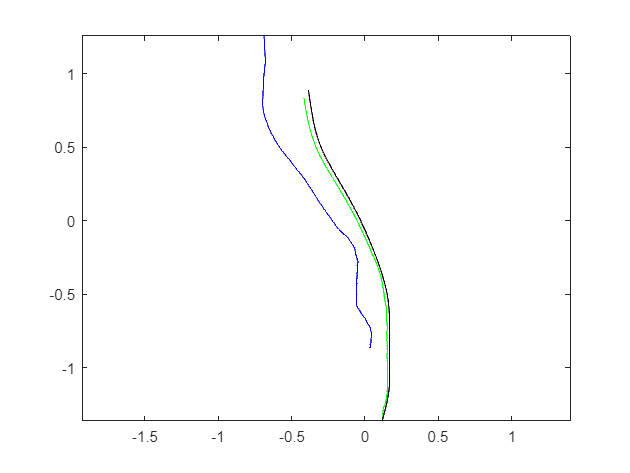

plot(m_o(1, :), m_o(2,:), 'g')
axis equal
hold on
plot(enc_o(1,:), enc_o(2,:), 'k')
plot(s_o(:,1), s_o(:,2), 'b')

**SECTION: computing uncertainty ellipsoids from the sensor results for grid points**

ttis struct is going to store all the information needed to build the ellipsoids,

vec_struct = repmat(struct('cov_mat', [], 'avg_point', [], 'phi', [], 'a', [], 'b', []), num_points, 1);

grid and ellipse generation with respect to r.f. "o"

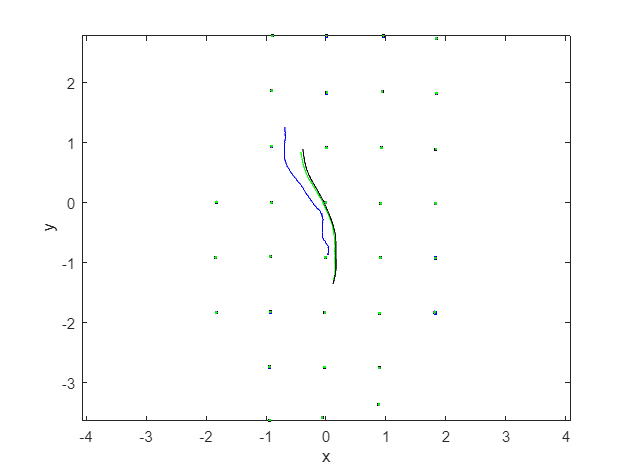

[pl, vec_struct, ~] = plot_grid(folder_path_grid, Moa, num_points, true, vec_struct, "-b");
xlabel('x');
ylabel('y');
axis equal;
hold off

**SECTION: computing uncertainty ellipsoids from the sensor **

Compute the results for every point. First we get vectors of values inside the struct which are used to fit results.

avg_point_vec = [vec_struct.avg_point];
phi_vec = [vec_struct.phi];
a_vec = [vec_struct.a];
b_vec = [vec_struct.b];

Building the fitting functions.

fitresultnl_phi = fit([avg_point_vec(1, :)', avg_point_vec(2, :)'], phi_vec(:), 'poly33');
fitresultnl_a = fit([avg_point_vec(1, :)', avg_point_vec(2, :)'], a_vec(:), 'poly23');
fitresultnl_b = fit([avg_point_vec(1, :)', avg_point_vec(2, :)'], b_vec(:), 'poly23');

Plotting the fitting functions for the angle.

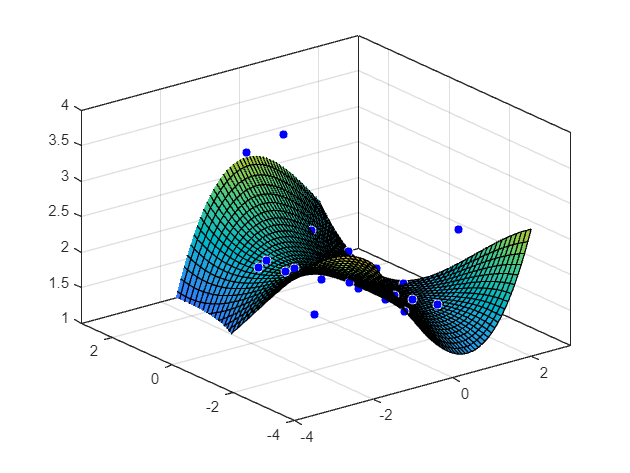

scatter3(avg_point_vec(1, :), avg_point_vec(2, :), phi_vec(:));
hold on;
plot(fitresultnl_phi, [avg_point_vec(1, :)', avg_point_vec(2, :)'], phi_vec(:))
xlim([-4 3])
ylim([-4 3])
zlim([1 4])
hold off

Plotting the fitting functions for the a ellipse axis.

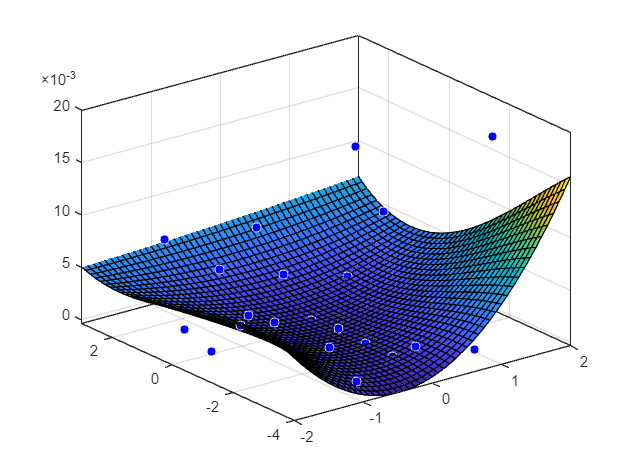

scatter3(avg_point_vec(1, :), avg_point_vec(2, :), a_vec(:));
hold on;
plot(fitresultnl_a, [avg_point_vec(1, :)', avg_point_vec(2, :)'], a_vec(:))
xlim([-2 2])
ylim([-4 3])
hold off

Plotting the fitting functions for the b ellipse axis.

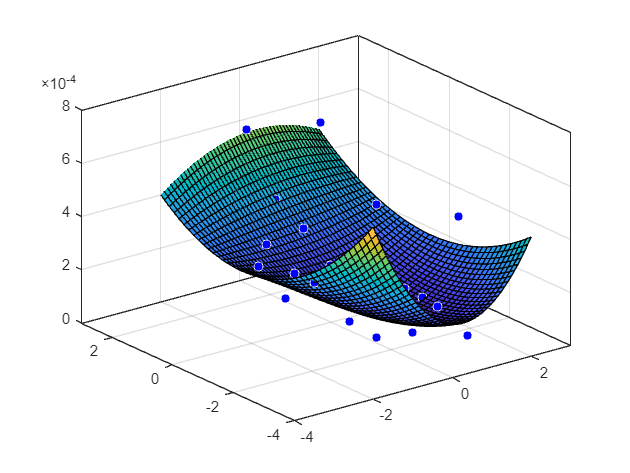

scatter3(avg_point_vec(1, :), avg_point_vec(2, :), b_vec(:));
hold on;
plot(fitresultnl_b, [avg_point_vec(1, :)', avg_point_vec(2, :)'], b_vec(:))
xlim([-4 3])
ylim([-4 3])
hold off

**SECTION: computing uncertainty ellipsoids from the encoders results**

The uncertainty of the omega_k values. Here the uncertainty values for the encoders are defined.

unc_R_left = 0.0014

unc_R_left = 0.0014

unc_R_right = 0.0014

unc_R_right = 0.0014

unc_base = 0.001  

unc_base = 1.0000e-03

S_initial = diag([unc_R_left, unc_R_right, unc_base, 0]);

The jacobian calculated from k=2, k=1 is defined, as the jacobian is calculated using k-1 and k-2. Therefore i=1 and i=2 are needed for i=3. 

uncertainty_matrices(1) = struct('I_matrix', zeros(3, 4), "Cov_matrix", zeros(3, 3), "Jacobian", zeros(3, 4), "S_matrix", S_initial, "k", 1);
uncertainty_matrices(2) = struct('I_matrix', zeros(3, 4), "Cov_matrix", zeros(3, 3), "Jacobian", zeros(3, 4), "S_matrix", S_initial, "k", 1);

For loop to calculate all the uncertainty ellipsoids for the encoders.

for k = 2:(N1 - 1)
    uncertainty_matrices(k).k = k;
    % Get the jacobian of this iteration
    % The jacobian of iteration k is used to calculate the covariance of k+1
    uncertainty_matrices(k).Jacobian = J_func(phi_new(k, 1), phi_new(k, 2), enc_l(k) - enc_l(k-1), enc_r(k) - enc_r(k-1), enc_N0, wheel_radius_L, wheel_radius_R, phi_new(k, 3), wheel_base);
    
    % The uncertainty of the w vector
    uncertainty_matrices(k).S_matrix = diag([unc_R_left, unc_R_right, unc_base, sqrt(uncertainty_matrices(k).Cov_matrix(3, 3))]);
    C_wk = uncertainty_matrices(k).S_matrix.^2;

    % The propagated uncertainty 
    uncertainty_matrices(k).I_matrix = uncertainty_matrices(k - 1).I_matrix  + uncertainty_matrices(k - 1).Jacobian * uncertainty_matrices(k - 1).S_matrix;

    % The covariance of k + 1 
    term1 = uncertainty_matrices(k).Jacobian * C_wk * uncertainty_matrices(k).Jacobian';
    term2 = uncertainty_matrices(k).Jacobian * uncertainty_matrices(k).S_matrix * uncertainty_matrices(k).I_matrix';
    term3 = uncertainty_matrices(k).I_matrix * uncertainty_matrices(k).S_matrix * uncertainty_matrices(k).Jacobian';
    
    differences = term1 + term2 + term3;
    uncertainty_matrices(k + 1).Cov_matrix = uncertainty_matrices(k).Cov_matrix +  differences; 
end

Make a vector of the uncertainty matrices.

k_vec = [uncertainty_matrices.k];
Cov_mat = [uncertainty_matrices.Cov_matrix];  
num = 3 * k_vec - 2;

Plotting the increasing uncertainty on x and y. Note that we only plot the 250 points starting from 250. In the covariance matrices index (1, 1) is the x uncertainty and (2, 2) is the y uncertainty, therefore the second one has +1.

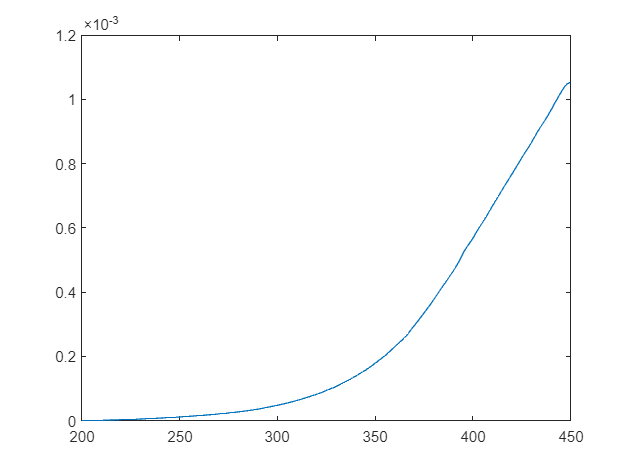

plot(k_vec(200:450), Cov_mat(1, num(200:450)))

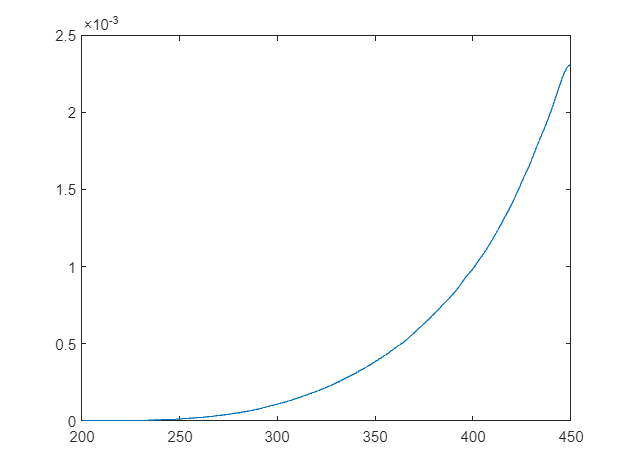

plot(k_vec(200:450), Cov_mat(2, num(200:450) + 1))

enc_cov_mats = [uncertainty_matrices(:).Cov_matrix];
enc_cov_mats =  reshape(enc_cov_mats, 3, 3, N1);
for i = 1:N1
    enc_cov_mats(:, :, i) = rotz(90) * enc_cov_mats(:, :, i) * rotz(90)';
end

**SECTION: plots the enc_o, m_o trajectory on the grid with both the uncertainty**

Ellipsoids from the sensor dataset and the encoder dataset. First plotting the grid.

[pl, vec_struct, theta_grid] = plot_grid(folder_path_grid, Moa, num_points, false, vec_struct, '-k');
hold on
xlabel('x');
ylabel('y');

Now plot the encoders and the middle point enc_o and m_o.

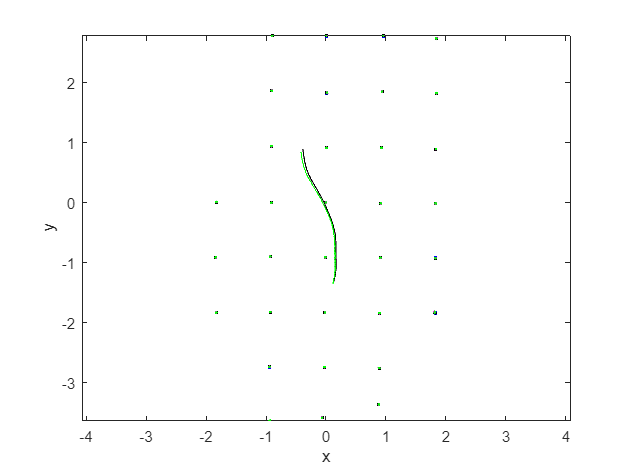

plot(enc_o(1,:), enc_o(2,:), 'k');
plot(m_o(1,:), m_o(2,:), 'g');
axis equal;
hold off;

For showing purposes let us plot the uncertainty ellipses for both the encoders (in black) and for the tracker trajectory (in red) for some points that are not correlated to each other.  

distance = 0;
step = 1500;
for i = step+1:step:(length(m_o))
    distance = distance + sqrt((m_o(1, i) - m_o(1, i  -step))^2 + (m_o(2,i) - m_o(2,i-step))^2);
    X0 = m_o(1, i);
    Y0 = m_o(2, i);
    
    % note the pi/2 added to rotate the ellipses rightly
    phi_eval = pi/2 + feval(fitresultnl_phi, X0, Y0);
    a_eval = feval(fitresultnl_a, X0, Y0);
    b_eval = feval(fitresultnl_b, X0, Y0);
    
    ellipse_x_r  = a_eval*cos(theta_grid);
    ellipse_y_r  = b_eval*sin(theta_grid);
    
    R = [cos(phi_eval) sin(phi_eval); -sin(phi_eval) cos(phi_eval)];
    r_ellipse = [ellipse_x_r; ellipse_y_r]' * R;
    
    plot(r_ellipse(:,1) + X0, r_ellipse(:, 2) + Y0,'-r', 'LineWidth', 2)
    hold on
end

for i = 1:size(enc_cov_mats, 3)    
    % Draw the error ellipse
    if (mod(i,15)==0)
        [eigvec, eigval] = eig(enc_cov_mats(1:2, 1:2, i));
        
        % Get the index of the largest eigenvector
        [largest_eigvec_ind_c, r] = find(eigval == max(max(eigval)));
        largest_eigvec = eigvec(:, largest_eigvec_ind_c);
        
        % Get the largest eigenvalue
        largest_eigval = max(max(eigval));
        
        % Get the smallest eigenvector and eigenvalue
        if(largest_eigvec_ind_c == 1)
            smallest_eigval = max(eigval(:,2));
            smallest_eigvec = eigvec(:,2);
        else
            smallest_eigval = max(eigval(:,1));
            smallest_eigvec = eigvec(1,:);
        end
        
        % Calculate the angle between the x-axis and the largest eigenvector
        angle = atan2(largest_eigvec(2), largest_eigvec(1));
        
        % This angle is between -pi and pi.
        % Let's shift it such that the angle is between 0 and 2pi
        if(angle < 0)
            angle = angle + 2*pi;
        end
           
        % Get the 95% confidence interval error ellipse
        chisquare_val = 2.4477;
        theta_grid = linspace(0,2*pi);
        phi = angle; 
        X0=enc_o(1, i);
        Y0=enc_o(2, i);
        a=chisquare_val*sqrt(largest_eigval);
        b=chisquare_val*sqrt(smallest_eigval);
        
        % the ellipse in x and y coordinates 
        ellipse_x_r  = a*cos( theta_grid );
        ellipse_y_r  = b*sin( theta_grid );
        
        %Define a rotation matrix
        R = [ cos(phi) sin(phi); -sin(phi) cos(phi) ];
        
        %let's rotate the ellipse to some angle phi
        r_ellipse = [ellipse_x_r;ellipse_y_r]' * R;
        plot(r_ellipse(:,1) + X0,r_ellipse(:,2) + Y0,'-k', 'LineWidth',1)
        hold on;
        
        mindata = min(min(enc_o(1:2, :)));
        maxdata = max(max(enc_o(1:2, :)));
        axis equal
        
        % Plot the eigenvectors
        quiver(X0, Y0, largest_eigvec(1)*sqrt(largest_eigval), largest_eigvec(2)*sqrt(largest_eigval), '-m', 'LineWidth',2);
        quiver(X0, Y0, smallest_eigvec(1)*sqrt(smallest_eigval), smallest_eigvec(2)*sqrt(smallest_eigval), '-g', 'LineWidth',2);
        
        % Set the axis labels
        hXLabel = xlabel('x');
        hYLabel = ylabel('y');
    end
end

Set axis limits and labels

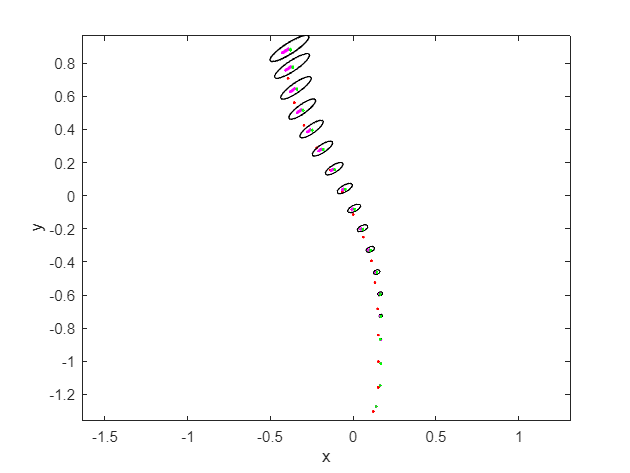

xlabel('x');
ylabel('y');
axis equal;
hold off

**SECTION: getting the sensor covariance matrices for any point**

For each point in the grid the covariance matrix parameters are stored inside a vector.

for i = 1:num_points
    e11(i) = vec_struct(i).cov_mat(1,1);
    e12(i) = vec_struct(i).cov_mat(1,2);
    e22(i) = vec_struct(i).cov_mat(2,2);
end

Building the fitting function using the values of the covariance matrix.

fitres_e11 = fit([avg_point_vec(1,:)', avg_point_vec(2,:)'], e11(:), 'poly44');
fitres_e12 = fit([avg_point_vec(1,:)', avg_point_vec(2,:)'], e12(:), 'poly44');
fitres_e22 = fit([avg_point_vec(1,:)', avg_point_vec(2,:)'], e22(:), 'poly44');

Plot the scatterplots for each of the variables

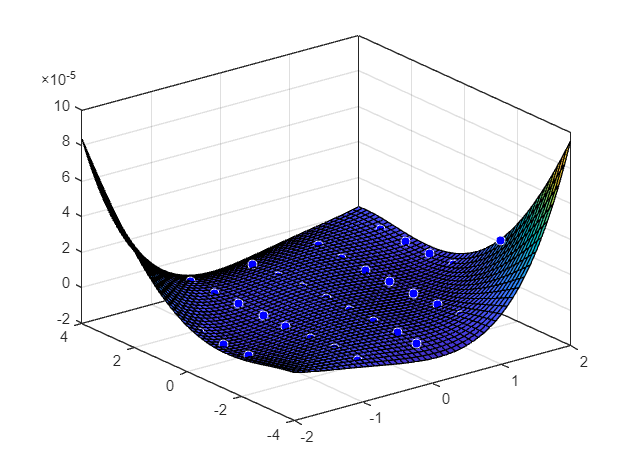

scatter3(avg_point_vec(1,:), avg_point_vec(2,:), e11(:));
hold on;
plot(fitres_e11, [avg_point_vec(1,:)', avg_point_vec(2,:)'], e11(:))
hold off

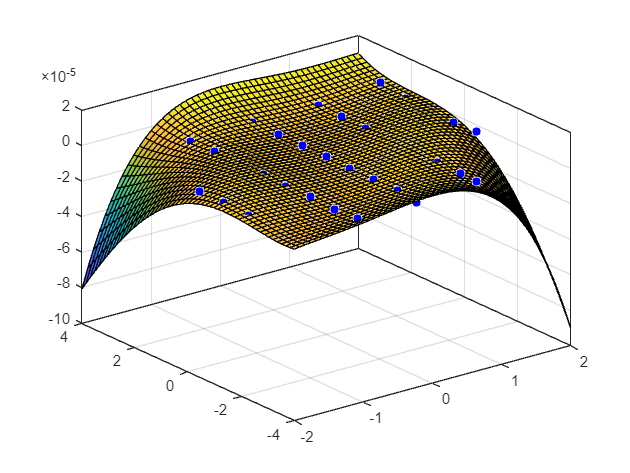

scatter3(avg_point_vec(1,:), avg_point_vec(2,:), e12(:));
hold on;
plot(fitres_e12, [avg_point_vec(1,:)', avg_point_vec(2,:)'], e12(:))
hold off

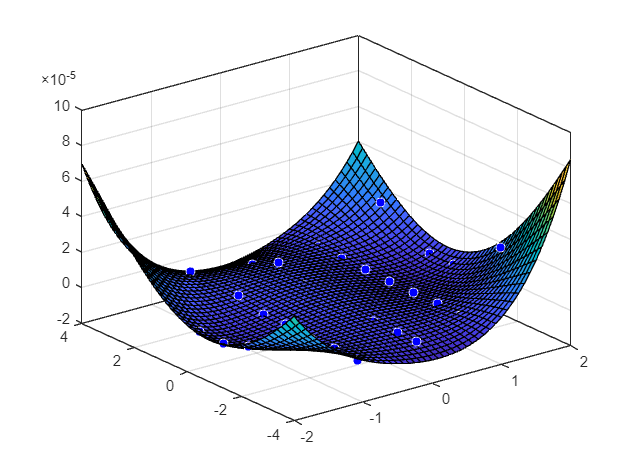

scatter3(avg_point_vec(1,:), avg_point_vec(2,:), e22(:));
hold on;
plot(fitres_e22, [avg_point_vec(1,:)', avg_point_vec(2,:)'], e22(:))
hold off

Apply the filter for each of the points. Then put the values of the covariance matrices in a vector.

el11 = fitres_e11(m_o(1, :),m_o(2, :))

el11 = 1.0e-05 *

    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0402    0.0404    0.0404    0.0404    0.0404    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403    0.0403


el12 = fitres_e12(m_o(1, :),m_o(2, :))

el12 = 1.0e-05 *

   -0.0153   -0.0153   -0.0153   -0.0153   -0.0153   -0.0153   -0.0153   -0.0153   -0.0153   -0.0153   -0.0153   -0.0153   -0.0156   -0.0156   -0.0156   -0.0156   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0154   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155   -0.0155


el22 = fitres_e22(m_o(1, :),m_o(2, :))

el22 = 1.0e-05 *

    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1577    0.1577    0.1577    0.1577    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1575    0.1576    0.1576    0.1576    0.1576    0.1576    0.1576    0.1576    0.1576    0.1576    0.1576


for i = 1:length(m_o(1, :))
    traj_mat(i, :) = [el11(i) el12(i) el22(i)];
end

**SECTION: synchronising**

The goal is to synchronize the two different trajectories such that the points coincide. This is done by filtering out the points at which the measurements do not move, and only start counting when a minimal threshold distance is travelled. 

The variables, the distance_s and distance_enc, are the distance from the starting point. The index_s and index_enc are the indices at which the distance is checked.

distance_s = 0;
distance_enc = 0;
index_s = 1;
index_enc = 1;
min_distance = 0.01;

Filter the distances such that the index starts at the point where the travelled distance is more than the minimal distance.

while distance_s < min_distance
    distance_s = sqrt((m_o(1, index_s) - m_o(1, 1))^2 + (m_o(2, index_s) - m_o(2, 1))^2);
    index_s = index_s + 1;
end

while distance_enc < min_distance
    distance_enc = sqrt( (enc_o(1, index_enc) - enc_o(1, 1))^2 + (enc_o(2, index_enc) - enc_o(2, 1))^2);
    index_enc = index_enc + 1;
end

Look at both values.

index_s

index_s = 1091

index_enc

index_enc = 187

Put the filtered points in a vector.

m_o_filtered = zeros(4, (length(m_o) - index_s));
for i=1:length(m_o_filtered)
    m_o_filtered(:, i) = m_o(:, i + index_s);
end

enc_o_filtered = zeros(4, (length(enc_o) - index_enc));
for i = 1:length(enc_o_filtered)
    enc_o_filtered(:, i) = enc_o(:, i + index_enc);
end

Get the timestamps of the encoders and sensors

t_s = trajectory((1 + index_s):end, end); 
t_enc = outputE((1 + index_enc):end, 3);

Make sure that the timestamps start at 0 by subtracting the first value.

t_s = t_s - t_s(1)

t_s =      0
     1
     2
     6
     7
     8
     9
    10
    11
    12


t_enc = t_enc - t_enc(1)

t_enc =      0
   102
   202
   300
   402
   502
   604
   703
   802
   901


Make a time series from these timestamps. 

T = datetime(1970, 1, 1, 0, 0, 0, 0,'TimeZone','UTC','F','uuuu-MM-dd''T''HH:mm:ss.SSS Z');
T_s = T + milliseconds(t_s);
T_enc = T + milliseconds(t_enc);

Create 2D arrays for both the encoder and the sensor that contain the position and the index, therefore both 2D arrays contain three columns.

pos_s = [m_o_filtered(1, :)' m_o_filtered(2, :)' [index_s + 1:length(trajectory)]'];
pos_enc = [enc_o_filtered(1, :)' enc_o_filtered(2, :)' [index_enc + 1:length(outputE)]'];

Convert the 2D arrays for the encoders and the positions to a timetable. This is done by including the timeseries

TT1 = array2timetable(pos_s, 'RowTimes', T_s);
TT2 = array2timetable(pos_enc, 'RowTimes', T_enc);

Take the positions and indices at which both timetables have a timestamp.

TT = synchronize(TT1, TT2, 'intersection')

TT = 234×6 timetable
                Time                 pos_s1     pos_s2     pos_s3    pos_enc1    pos_enc2    pos_enc3
    _____________________________    _______    _______    ______    ________    ________    ________

    1970-01-01T00:00:00.000 +0000    0.12048    -1.3486     1092     0.12529      -1.331       188   
    1970-01-01T00:00:00.102 +0000    0.12064    -1.3398     1179     0.12755     -1.3222       189   
    1970-01-01T00:00:00.202 +0000    0.12107    -1.3312     1265     0.12972     -1.3138       190   
    1970-01-01T00:00:00.300 +0000    0.12267    -1.3232     1352     0.13184     -1.3056       191   
    1970-01-01T00:00:00.402 +0000    0.1226

**SECTION: sensor fusion**

The encoders uncertainty is merged with the uncertainty of the sensor which in turn is stored in "fused_o".

for i = 1:length(TT.pos_enc3)
    Cx = [traj_mat(TT.pos_s3(i), 1) traj_mat(TT.pos_s3(i), 2); traj_mat(TT.pos_s3(i), 2) traj_mat(TT.pos_s3(i), 3)];
    Cz = [enc_cov_mats(1, 1, TT.pos_enc3(i)) enc_cov_mats(1, 2, TT.pos_enc3(i)); enc_cov_mats(2, 1, TT.pos_enc3(i)) enc_cov_mats(2, 2, TT.pos_enc3(i))];
    C_middle = Cz*inv(Cx + Cz)*Cx;
    
    C(i,:) = [C_middle(1,1) C_middle(1,2) C_middle(2,2)];
    
    fused_o(i,:) = Cx*inv(Cx + Cz)*[enc_o(1,TT.pos_enc3(i)) enc_o(2,TT.pos_enc3(i))]'+Cz*inv(Cx + Cz)*[m_o(1,TT.pos_s3(i)) m_o(2,TT.pos_s3(i))]';
end

Plot both trajectories along with the merged trajectory.

plot(m_o(1, :), m_o(2, :), 'g')
axis equal
hold on
plot(enc_o(1, :), enc_o(2, :), 'k')
plot(s_o(:, 1), s_o(:, 2), 'b')
plot(fused_o(:, 1), fused_o(:, 2), 'r')

Plot the merged, the sensor and the encoder uncertainty. This is only done once for every 10 points.  The following naming is used:

- "m" refers to the merged variant

- "s" refers to the sensor

- "e" refers to the encoder

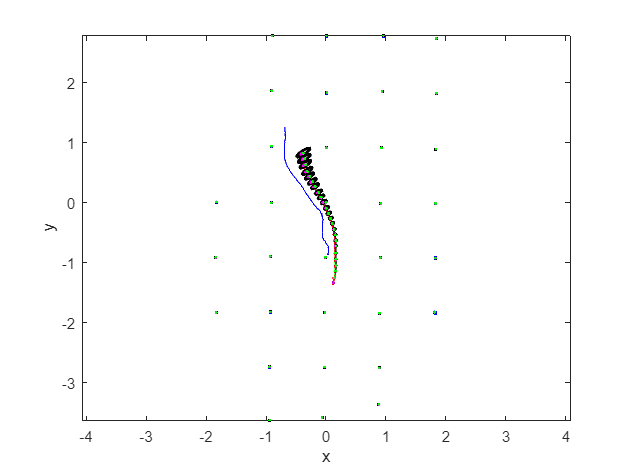

for i = 1:10:length(TT.pos_s3)
    % Make a covariance matrix from the points. The covariance matrix of
    % the encoders has to be rotated with 90 degrees as it starts out going
    % into the direction aligned with the x axis. However it is desired to
    % start out going aligned with the y axis.
    m_cov_mat = [C(i, 1) C(i, 2); C(i, 2) C(i, 3)];
    s_cov_mat = [traj_mat(TT.pos_s3(i), 1) traj_mat(TT.pos_s3(i), 2); traj_mat(TT.pos_s3(i), 2) traj_mat(TT.pos_s3(i), 3)];
    e_cov_mat = enc_cov_mats(1:2, 1:2, TT.pos_enc3(i));

    % Plot the covariance matrices
    plot_uncertainty(m_cov_mat, fused_o(i, 1:2), false, '-b');
    plot_uncertainty(s_cov_mat, [TT.pos_s1(i), TT.pos_s2(i)], false, '-r');
    [pl, ~, ~, ~, ~] = plot_uncertainty(e_cov_mat, [TT.pos_enc1(i), TT.pos_enc2(i)], true, '-k');
    hold on
end

% Plot the grid
[pl, vec_struct, ~] = plot_grid(folder_path_grid, Moa, num_points, false, vec_struct, "-b");

% set axis limits and labels
xlabel('x');
ylabel('y');
axis equal;
hold off

**Function** that plots the covariance ellipsoid at a certain point given the coordinates and the uncertainty matrix.

function [pl, theta_grid, phi, a, b] = plot_uncertainty(cov_mat, coordinates, quivers, color)
    % Get the eigenvalues from the covariance matrix.
    [eigvec, eigval] = eig(cov_mat);
    
    % Get the largest eigenvalue.
    largest_eigval = max(max(eigval));

    % Get the index of the largest eigenvector.
    [largest_eigvec_ind_c, ~] = find(eigval == largest_eigval);
    largest_eigvec = eigvec(:, largest_eigvec_ind_c);

    % Get the smallest eigenvector and eigenvalue.
    if(largest_eigvec_ind_c == 1)
        smallest_eigval = max(eigval(:, 2));
        smallest_eigvec = eigvec(:, 2);
    else
        smallest_eigval = max(eigval(:, 1));
        smallest_eigvec = eigvec(:, 1);
    end
    
    % Calculate the angle between the x-axis and the largest eigenvector.
    angle = atan2(largest_eigvec(2), largest_eigvec(1));
    
    % This angle is between -pi and pi.
    % Shift it such that the angle is between 0 and 2pi.
    if(angle < 0)
        angle = angle + 2*pi;
    end
    
    % Get the 95% confidence interval error ellipse.
    chisquare_val = 2.4477;
    theta_grid = linspace(0, 2 * pi);
    phi = angle;
    X0 = coordinates(1);
    Y0 = coordinates(2);
    a = chisquare_val * sqrt(largest_eigval);
    b = chisquare_val * sqrt(smallest_eigval);
    
    % The ellipse in x and y coordinates.
    ellipse_x_r  = a * cos(theta_grid);
    ellipse_y_r  = b * sin(theta_grid);
    
    % Define a rotation matrix.
    R = [cos(phi) sin(phi); -sin(phi) cos(phi)];
    
    % Rotate the ellipse to some angle phi.
    r_ellipse = [ellipse_x_r; ellipse_y_r]' * R;
    
    % Draw the error ellipse.
    pl = plot(r_ellipse(:, 1) + X0, r_ellipse(:, 2) + Y0, color, 'LineWidth', 2);

    % If the quivers have to be plotted, then include them
    if (quivers)
        quiver(X0, Y0, largest_eigvec(1)*sqrt(largest_eigval), largest_eigvec(2)*sqrt(largest_eigval), '-m', 'LineWidth', 2);
        quiver(X0, Y0, smallest_eigvec(1)*sqrt(smallest_eigval), smallest_eigvec(2)*sqrt(smallest_eigval), '-g', 'LineWidth', 2);
    end
       hold on;
end

**Function** that plots all the points in a folder path. All the points are rotated using a rotation matrix Moa. Within the folder there should be num_points data points with the incrementing name "num_points_" + index

function [pl, vec_struct, theta_grid] = plot_grid(folder_path, Moa, num_points, fill_struct, vec_struct, color)
    % for each point on the grid load the relative data file that contains information about the position (r.f. camera "a")
    for i = 1:num_points
        var_name = sprintf('data_point_%d', i);
        file_name = sprintf('data_point_%d.csv', i);
        data_path = fullfile(folder_path, file_name);
        eval(sprintf('%s = load(''%s'');', var_name, data_path));
    end

    % Define variables that are accessible
    for i = 1:num_points
        % Get the name of the datapoint and store it inside the variable
        % sensor
        name = sprintf('data_point_%d', i);
        eval(sprintf('sensor = %s;', name));

        % Get the amount of measurement of a certain point in the grid
        N2 = length(sensor(:, 1));

        % Get the x, y and z component of the point given in frame a and
        % put it in a vector. Do the same for the mean x y and z
        points_a = [sensor(:, 1:3), ones(N2, 1)];
        mean_p_a = [mean(sensor(:, 1)), mean(sensor(:, 2)), mean(sensor(:, 3)), 1];
        mean_p_o = Moa * mean_p_a';
        points_p = zeros(N2, 4);
    
        % Get each point also in the origin reference frame
        for j = 1:N2
            points_p(j, :) = Moa * points_a(j, :)';
        end

        % Plot each point in the origin reference frame as well as the mean
        plot(points_p(:, 1), points_p(:, 2), '.b');
        plot(mean_p_o(1), mean_p_o(2), '.k');
        
        % Get the matrices of the mean 
        mean_mat = repmat(mean_p_o', N2, 1);
        cov_mat = cov(points_p - mean_mat);
        
        % Plot the covariance matrix at the point
        [pl, theta_grid, phi, a, b] = plot_uncertainty(cov_mat(1:2, 1:2), mean(points_p), true, color);

        if (fill_struct)
            s_covmat = struct('cov_mat', cov_mat, 'avg_point', mean_p_o, 'phi', phi, 'a', a, 'b', b);
            vec_struct(i) = s_covmat;
        end
    end
end